## МИУ

MFIE - граничное условие для магнитного опля

#### H - поляризация

Цилиндр круглого сечения

04-02-21

close all;
clear variables;
tic; % замер времени

Входные параметры


R = 2;
N = 400;
delta_phi = 360/N;
dx = 2*R*sind(delta_phi/2);


k = 2*pi; 
phi_grad = 0; % угол падения волны [град]

Замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;
    D0 = kdx*(1+(1i*2/pi)*(log(gamma*kd4)-1));
    D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
    D2 = kdx*(1+(1i*2/pi)*(log(2*gamma*kd4)-1));

Порог

% treshold = 1*dx;
% str = sprintf('Будет посчитано %.f матричных элементов через формулу',  fix(treshold/dx));
% disp(str)
% 
% if treshold == dx
%     warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
% elseif treshold <= dx
%     warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
%     str2 = sprintf('Порог были принят равным dx = %.i',  dx);
%     disp(str2)
%     treshold = dx;
% end

Генерация точек

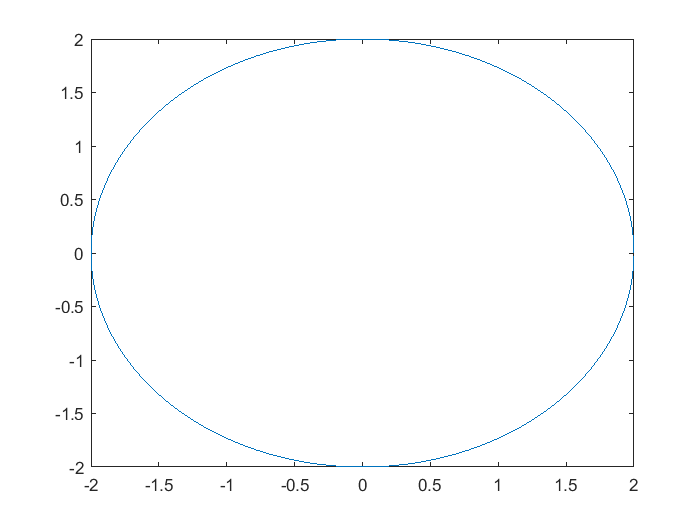

delta_phi = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = R*sind(delta_phi*(i-1));
    x(i) = R*cosd(delta_phi*(i-1));
end

plot(x,z)

Посчитаем t для каждого отрезка

for i = 1 : N
    if i == N
        tx(i) = -((x(1)-x(i)))/dx;
        tz(i) = -((z(1)-z(i)))/dx;
    else
        tx(i) = -(x(i+1)-x(i))/dx;
        tz(i) = -(z(i+1)-z(i))/dx;
    end
end

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    a = -90;
    matrix = [cosd(a),-sind(a); sind(a),cosd(a)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Координаты центров отрезков

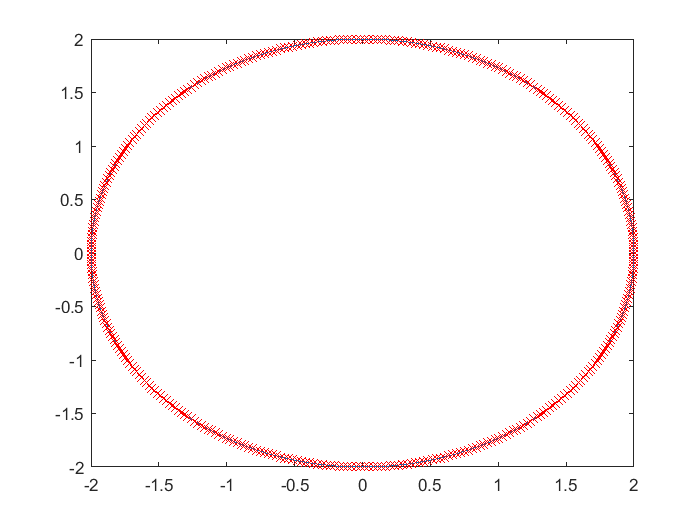

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx')

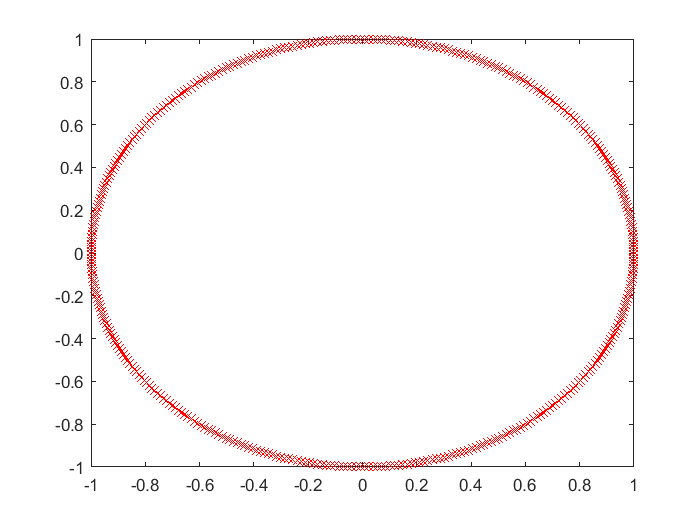


% визуализируем tx и tz
plot(tx, tz, 'rx')

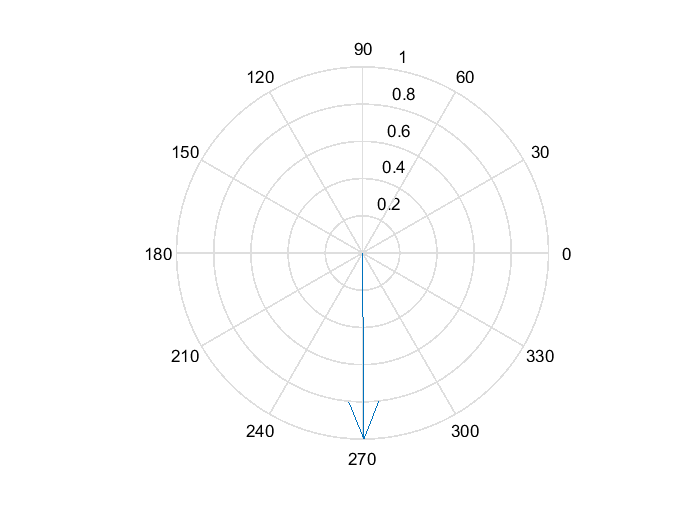

compass(tx(1),tz(1))

Изучим один цикл


count = 0;
for m = 1 : N
    
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
    %   Координаты в исходной системе координат (в ГСК)
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
           

Т.к. взяли на начало середину отрезка то тут будет

        % координаты в локальных координатах
        umn = xmO2;
        wmn = zmO2;

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
%       Расчет матричных элементов (в ЛСК)
        
        Hus = 0;
        Hws = 0;
        if n == m %r < 0.001*dx 
            
            % y - cоставляющая 
            Hys = -0.5;
            
        elseif abs(n - m) < 1.5 %r <= 2*dx
            % y - cоставляющая                     
            umn_plus_dx2 = umn + dx/2;
            umn_minus_dx2 = umn - dx/2;
            Hys = -(1i/8*wmn*k^2*dx + 1/(2*pi)*(atan(umn_plus_dx2/wmn) - atan(umn_minus_dx2/wmn)));
                 
        else 
            % y - cоставляющая
            rmn = sqrt(umn^2 + wmn^2);    
            Hys = -1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));  
            
        end
        
%       символ кронкера
        if m == n
            kronker = 1;
        else 
            kronker = 0;
        end
        
        % расчет матричнх элементов 
        Zmn(m,n) = kronker + Hys;
        
    end
end
 

Расчет падающего поля

for m=1:N
    nxm = nx(m);
    nzm = nz(m);
    
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    
    % Определим координаты
    xm = x_midle(m);
    zm = z_midle(m);
    
%   Итоговое падающее поле
      Hi(m,1) = -exp(cx*xm+cz*zm); 
end

Посчитаем токи и построим график

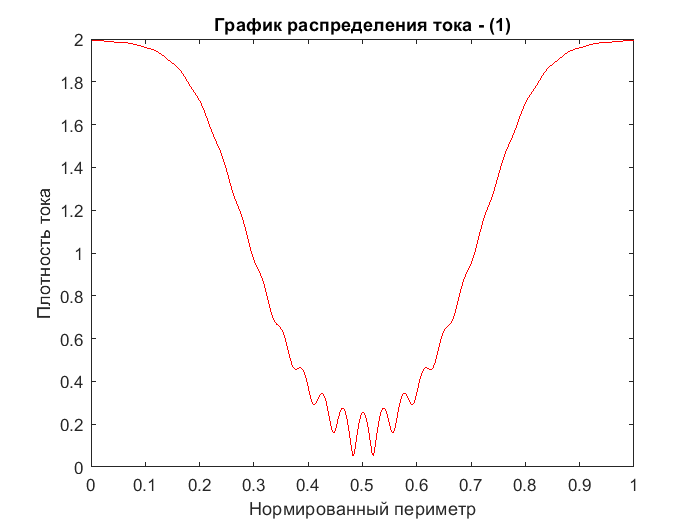

% расчеток токов ВИ 
I=Zmn\Hi;
       
% номера ВИ для графика 
n_for_graf = zeros(1, N);
for i = 1 : N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

% ось X в относительных единицах
figure;
plot(n_for_graf/(N), abs(I), 'r');
title('График распределения тока - (1)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

Сделаем счетчик для графика в градусах

% Берем угол точки в середине отрезка
begin_phi = delta_phi/2;
phi_for_graf = [];
for i = 1 : N 
    count = begin_phi + delta_phi*(i-1);
    phi_for_graf(i) = count;
end

 "Реальный токи"

В данном примере задается единичное магнитное поле. В Е - поляризации

задавалось едичиное електрчиеское поле. Чтоб их сравнить необходимо

умножить на 1/etta0

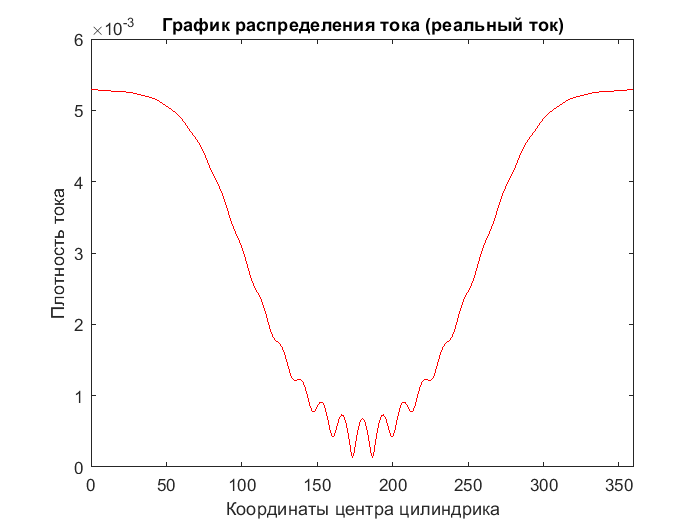

I_real = I/(120*pi);

figure;
plot(phi_for_graf, abs(I_real), 'r');
title('График распределения тока (реальный ток)'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0,360])
ylabel('Плотность тока');

Запись в файл токов

% name_file = strcat('I_MFIE_MIE_Hpol_circle_',  num2str(N), '.dat'); % в имея файла добавил число отрезков автоматом 
% 
% f01 = fopen(name_file,'w');
% 
% for n=1:N
%     fprintf(f01,' %10.5f %10.5f\n', phi_for_graf(n), abs(I_real(n))*1000);
% end
% 
% fclose(f01);

## ЭПР

for p = 1 : 721
    Sum_H = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k*cosd(phi);
    cz = - 1i*k*sind(phi);

    for n = 1 : N
       txn = tx(n);
       tzn = tz(n);
       xn = x_midle(n);
       zn = z_midle(n);
       
       Sum_H = Sum_H + 1/4*I(n)*k*dx*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
    end
    
    RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA ,RCS,'r-');

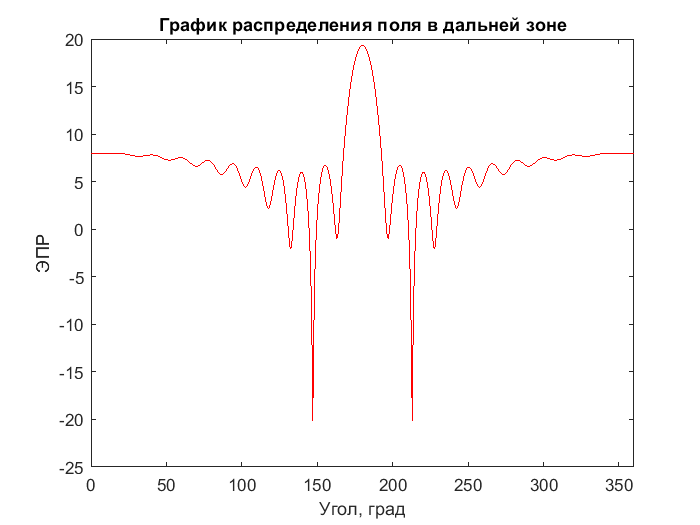

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

Запись в файл ЭПР

% % f02 = fopen('DA_MFIE_MIE_Hpol_circle.dat','w');
% % for p = 1 : 721
% %     fprintf(f02, ' %10.5f %10.5f\n', phi_for_graf_DA(p), RCS(p));
% % end
% % fclose(f02);

Результаты замера времени 

time = toc